% clear;
% close all;
% clc;

addpath('..\funcs');
load ..\..\matlab\lateral\all_0_0.5_0_0.05_Iattn_0.02.mat
% cd C:\zheng\mywork\attentioncolumn\paper\figure3_notused

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 4;
steps = size(orderSheet,1);

## Parameter plane (Iattn=0.02)

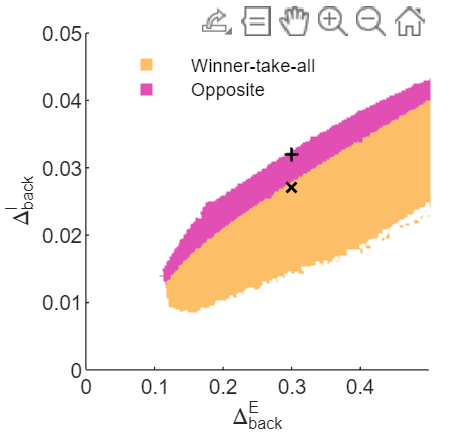

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

% lateral and order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FCBF67"); % yellow
    hold on
end

% lateral disagree, order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lateralSheet(i,j,4)==0 && lateralSheet(i,j,5)==0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end


roi = roi == 1;

% plot
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#E14FB4"); % magenta
end

% paint white
% gamma/+beta but order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s3 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white
    hold on
end

scatter(0.3, 0.027,30, "x","MarkerEdgeColor","k","LineWidth",1);
scatter(0.3, 0.032,30, "+","MarkerEdgeColor","k","LineWidth",1);
xlabel("\Delta_{back}^{E}");
ylabel("\Delta_{back}^{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Winner-take-all", "Opposite"],"Location","northwest");
legend boxoff;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('paraPlane02', '-dpng', '-r600');
% print('paraPlane02', '-depsc', '-r600');


## lateral 0.18

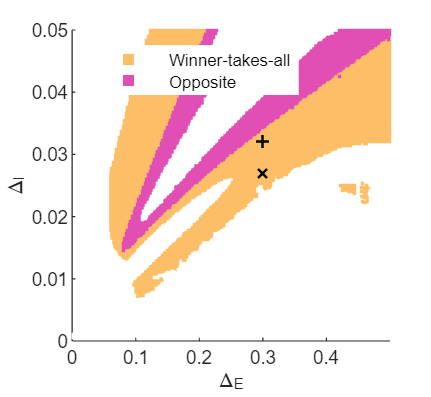

addpath('C:\zheng\mywork\attentioncolumn\matlab\funcs');
load C:\zheng\mywork\attentioncolumn\matlab\lateral\all_0_0.5_0_0.05_Iattn_0.02_lateral_0.18.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 4;
steps = size(orderSheet,1);

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

% lateral and order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FCBF67"); % yellow
    hold on
end

% lateral disagree, order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lateralSheet(i,j,4)==0 && lateralSheet(i,j,5)==0 && level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end


roi = roi == 1;

% plot
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#E14FB4"); % magenta
end

% paint white
% gamma/+beta but order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s3 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white
    hold on
end

scatter(0.3, 0.027,30, "x","MarkerEdgeColor","k","LineWidth",1);
scatter(0.3, 0.032,30, "+","MarkerEdgeColor","k","LineWidth",1);
xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Winner-takes-all", "Opposite"],"Location","northwest");
legend boxoff;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('paraPlaneLateral018', '-dpng', '-r600');
print('paraPlaneLateral018', '-depsc', '-r600');

## Make mark

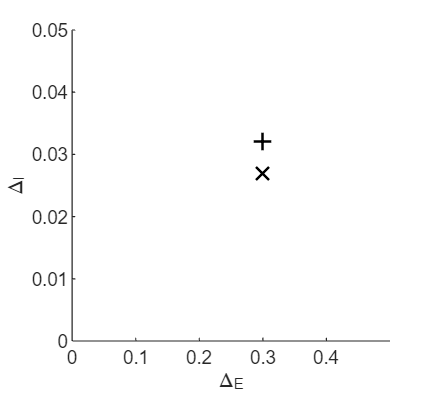

figure();
scatter(0.3, 0.027,60, "x","MarkerEdgeColor","k","LineWidth",1);
hold on;
scatter(0.3, 0.032,55, "+","MarkerEdgeColor","k","LineWidth",1);
xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('marks', '-dpng', '-r600');
print('marks', '-depsc', '-r600');

## bar chart

cd C:\zheng\mywork\attentioncolumn\paper\figure3
addpath('C:\zheng\mywork\attentioncolumn\matlab\funcs');

Delta_e = 0.3;
Delta_i = 0.032;
Iattn = 0.02;
alltime = 4000;
prd = 100000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, alltime);
PET = getPET(v(:,end-prd:end,:),g(:,:,end-prd:end,:)); 
oneTwo = squeeze(PET(10,1,:));
twoOne = squeeze(PET(2,9,:));

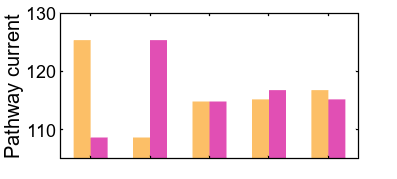

figure();
b = bar([oneTwo,twoOne],'EdgeColor','none','BarWidth',1);
b(1).FaceColor = "#FCBF67";
b(2).FaceColor = "#E14FB4";
ylim([1.05e2 1.3e2]);
set(gca,'XTickLabels',[]);
ylabel("Pathway current");

x0 = 0; y0 = 0; width = 6; height = 2.7;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('barUp', '-dpng', '-r600');
print('barUp', '-dsvg', '-r600');

Delta_e = 0.3;
Delta_i = 0.027;
Iattn = 0.02;
alltime = 4000;
prd = 100000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, alltime);
PET = getPET(v(:,end-prd:end,:),g(:,:,end-prd:end,:)); 
oneTwo = squeeze(PET(10,1,:));
twoOne = squeeze(PET(2,9,:));

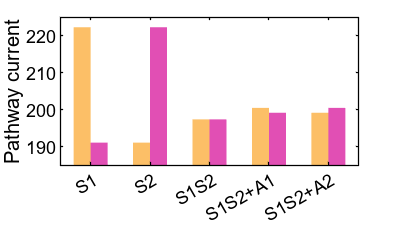

figure();
b = bar([oneTwo,twoOne],'EdgeColor','none','BarWidth',1);
b(1).FaceColor = "#FCBF67";
b(2).FaceColor = "#E14FB4";
ylim([1.85e2 2.25e2]);
set(gca,'XTickLabels',[]);
xticklabels(["S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"]);
ylabel("Pathway current");

x0 = 0; y0 = 0; width = 6; height = 3.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('barDown', '-dpng', '-r600');
print('barDown', '-dsvg', '-r600');

## make legend

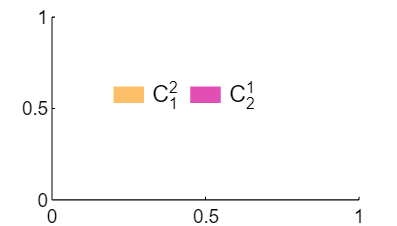

figure();
axis([0 1 0 1]);
rectangle('Position',[0.2,0.53,0.1,0.09],'FaceColor',"#FCBF67",'EdgeColor','none',...
    'LineWidth',0.1);
hold on;
rectangle('Position',[0.45,0.53,0.1,0.09],'FaceColor',"#E14FB4",'EdgeColor','none',...
    'LineWidth',0.1);
text(0.32, 0.57, "C_{1}^{2}");
text(0.57, 0.57, "C_{2}^{1}");

x0 = 0; y0 = 0; width = 6; height = 3.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('barLegend', '-dpng', '-r600');
print('barLegend', '-dsvg', '-r600');

## change lateral: up

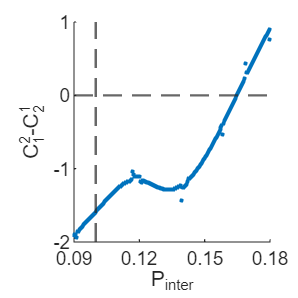

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.032_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3
PETAsheet = PETAsheet*0.001;

Delta_i_start = 0.09;
Delta_i_end = 0.18; 

steps = 201;

sz = 3;
x = linspace(Delta_i_start,Delta_i_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% find zero point
z = y2 - y1; 
[~, idxP] = min(z(z>0));
xZero = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
% xline(xZero,"--","LineWidth",1);
xline(0.1,"--","LineWidth",1);
yline(0,"--","LineWidth",1);

xlim([0.09 0.18]);
ylim([-2 1]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{inter}");
% axis tight;
ylabel("C_{1}^{2}-C_{2}^{1}");
xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('cLateralUp', '-dpng', '-r600');
print('cLateralUp', '-dsvg', '-r600');

## change lateral: down

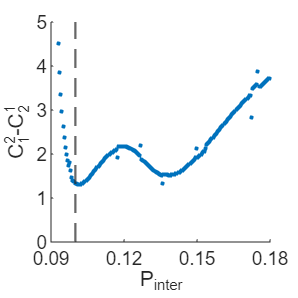

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.027_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

PETAsheet = PETAsheet*0.001;

Delta_i_start = 0.09;
Delta_i_end = 0.18; 

steps = 201;

sz = 3;
x = linspace(Delta_i_start,Delta_i_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% % find zero point
% z = y2 - y1; 
% [~, idxP] = min(z(z>0));
% x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
% s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);
% yline(0,'LineWidth',1);
xline(0.1,"--","LineWidth",1);

xlim([0.09 0.18]);
ylim([0 5]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{inter}");
ylabel("C_{1}^{2}-C_{2}^{1}");
xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('cLateralDown', '-dpng', '-r600');
print('cLateralDown', '-dsvg', '-r600');

## change lateral, order safe UP

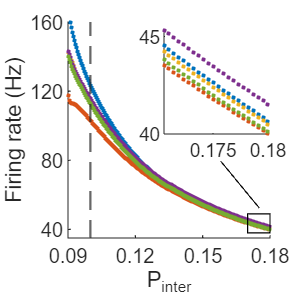

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.032_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

Delta_i_start = 0.09;
Delta_i_end = 0.18; 

steps = 201;
finalRsheet = finalRsheet*1000;
zoomSt = 180;

sz = 3;
x = linspace(Delta_i_start,Delta_i_end,size(PETAsheet,1));
y1 = finalRsheet(:,1);
y2 = finalRsheet(:,2);
y3 = finalRsheet(:,3);
y4 = finalRsheet(:,4);
y5 = finalRsheet(:,5);

figure();
s1 = scatter(x,y1,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
s3 = scatter(x,y3,sz,'filled','MarkerFaceColor',"#EDB120");
s4 = scatter(x,y4,sz,'filled','MarkerFaceColor',"#7E2F8E");
s5 = scatter(x,y5,sz,'filled','MarkerFaceColor',"#77AC30");
xline(0.1,"--","LineWidth",1);

rectangle('Position',[0.17 38 0.01 11],"LineWidth",0.5);
annotation('line',[.74 .87],[.46 .302]); % x x y y

xlim([0.09 0.18]);
ylim([35 160]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{inter}");
ylabel("Firing rate (Hz)");
yticks([40 80 120 160]);
xticks([0.09 0.12 0.15 0.18]);

zoomIn = axes('Position',[0.55 0.55 0.35 0.35]);
box on;

s6 = scatter(x(zoomSt:end),y1(zoomSt:end),sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s7 = scatter(x(zoomSt:end),y2(zoomSt:end),sz,'filled','MarkerFaceColor',"#D95319");
s8 = scatter(x(zoomSt:end),y3(zoomSt:end),sz,'filled','MarkerFaceColor',"#EDB120");
s9 = scatter(x(zoomSt:end),y4(zoomSt:end),sz,'filled','MarkerFaceColor',"#7E2F8E");
s10 = scatter(x(zoomSt:end),y5(zoomSt:end),sz,'filled','MarkerFaceColor',"#77AC30");
axis tight;

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('orderUp', '-dpng', '-r600');
print('orderUp', '-dsvg', '-r600');

## change lateral, order safe DOWN

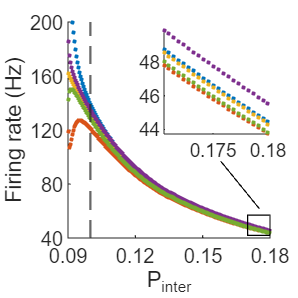

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.027_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

Delta_i_start = 0.09;
Delta_i_end = 0.18; 

steps = 201;
finalRsheet = finalRsheet*1000;
zoomSt = 180;

sz = 3;
x = linspace(Delta_i_start,Delta_i_end,size(PETAsheet,1));
y1 = finalRsheet(:,1);
y2 = finalRsheet(:,2);
y3 = finalRsheet(:,3);
y4 = finalRsheet(:,4);
y5 = finalRsheet(:,5);

figure();
s1 = scatter(x,y1,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
s3 = scatter(x,y3,sz,'filled','MarkerFaceColor',"#EDB120");
s4 = scatter(x,y4,sz,'filled','MarkerFaceColor',"#7E2F8E");
s5 = scatter(x,y5,sz,'filled','MarkerFaceColor',"#77AC30");
xline(0.1,"--","LineWidth",1);

rectangle('Position',[0.17 42 0.01 15],"LineWidth",0.5);
annotation('line',[.74 .87],[.46 .3]); % x x y y

xlim([0.09 0.18]);
ylim([40 200]);
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{inter}");
ylabel("Firing rate (Hz)");
yticks([40 80 120 160 200]);
xticks([0.09 0.12 0.15 0.18]);

zoomIn = axes('Position',[0.55 0.55 0.35 0.35]);
box on;

s6 = scatter(x(zoomSt:end),y1(zoomSt:end),sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s7 = scatter(x(zoomSt:end),y2(zoomSt:end),sz,'filled','MarkerFaceColor',"#D95319");
s8 = scatter(x(zoomSt:end),y3(zoomSt:end),sz,'filled','MarkerFaceColor',"#EDB120");
s9 = scatter(x(zoomSt:end),y4(zoomSt:end),sz,'filled','MarkerFaceColor',"#7E2F8E");
s10 = scatter(x(zoomSt:end),y5(zoomSt:end),sz,'filled','MarkerFaceColor',"#77AC30");
axis tight;

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('orderDown', '-dpng', '-r600');
print('orderDown', '-dsvg', '-r600');

## sum of current: L5E

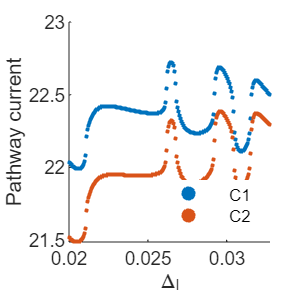

load C:\zheng\mywork\attentioncolumn\matlab\lateral\PET_0.3_0.3_0.02_0.03275_Iattn_0.02.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

Delta_i_start = 0.02;
Delta_i_end = 0.03275; 

steps = 201;
pop1 = 5;
sz = 3;

x = linspace(Delta_i_start,Delta_i_end,size(PETA,1));
exc1 = PETA(:,pop1,1,4) + PETA(:,pop1,3,4) + PETA(:,pop1,5,4) + PETA(:,pop1,7,4);
inh1 = PETA(:,pop1,2,4) + PETA(:,pop1,4,4) + PETA(:,pop1,6,4) + PETA(:,pop1,8,4);

exc2 = PETA(:,pop1+8,1+8,4) + PETA(:,pop1+8,3+8,4) + PETA(:,pop1+8,5+8,4) + PETA(:,pop1+8,7+8,4);
inh2 = PETA(:,pop1+8,2+8,4) + PETA(:,pop1+8,4+8,4) + PETA(:,pop1+8,6+8,4) + PETA(:,pop1+8,8+8,4);


figure();
s1 = scatter(x,exc1+inh1,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s2 = scatter(x,exc2+inh2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);
% yline(0,'LineWidth',1);

xlim([Delta_i_start Delta_i_end]);
% ylim([0 0.5]);
legend([s1 s2],["C1","C2"],"Location","Southeast");
legend boxoff;
xlabel("\Delta_{I}");
ylabel("Pathway current");
% xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('try', '-dpng', '-r600');
print('try', '-dsvg', '-r600');

## sum of current: L2/3E

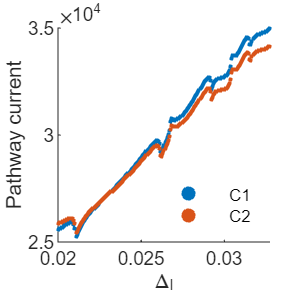

load C:\zheng\mywork\attentioncolumn\matlab\lateral\PETN_0.3_0.3_0.02_0.03275_Iattn_0.02.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

Delta_i_start = 0.02;
Delta_i_end = 0.03275; 

steps = 201;
pop1 = 1;
sz = 3;

x = linspace(Delta_i_start,Delta_i_end,size(PETA,1));
exc1 = PETA(:,pop1,3,4) + PETA(:,pop1,5,4) + PETA(:,pop1,7,4) + 1200;
inh1 = PETA(:,pop1,2,4) + PETA(:,pop1,4,4) + PETA(:,pop1,6,4) + PETA(:,pop1,8,4);
ctp1 = sum(PETA(:,10,:,4),3);

exc2 = PETA(:,pop1+8,3+8,4) + PETA(:,pop1+8,5+8,4) + PETA(:,pop1+8,7+8,4);
inh2 = PETA(:,pop1+8,2+8,4) + PETA(:,pop1+8,4+8,4) + PETA(:,pop1+8,6+8,4) + PETA(:,pop1+8,8+8,4);
ctp2 = sum(PETA(:,2,:,4),3);


figure();
s1 = scatter(x,exc1-inh1,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s2 = scatter(x,exc2-inh2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);
% yline(0,'LineWidth',1);

xlim([Delta_i_start Delta_i_end]);
% ylim([0 0.5]);
legend([s1 s2],["C1","C2"],"Location","Southeast");
legend boxoff;
xlabel("\Delta_{I}");
ylabel("Pathway current");
% xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('try', '-dpng', '-r600');
print('try', '-dsvg', '-r600');

## try change lateral and pathway current

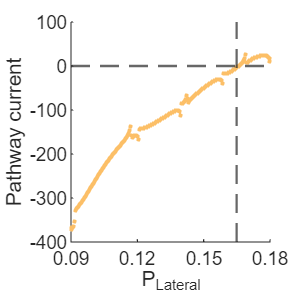

load C:\zheng\mywork\attentioncolumn\matlab\lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.032_Iattn_0.02_steps_201.mat
cd C:\zheng\mywork\attentioncolumn\paper\figure3

PETA = PETAsheet; pop1 = 1;
Delta_i_start = 0.09;
Delta_i_end = 0.18; 

steps = 201;

sz = 3;
x = linspace(Delta_i_start,Delta_i_end,size(PETA,1));
exc1 = PETA(:,pop1,1,4) + PETA(:,pop1,3,4) + PETA(:,pop1,5,4) + PETA(:,pop1,7,4)+ 0.011*10341;
inh1 = PETA(:,pop1,2,4) + PETA(:,pop1,4,4) + PETA(:,pop1,6,4) + PETA(:,pop1,8,4);
ctp1 = sum(PETA(:,10,:,4),3);
y1 = exc1-inh1;

exc2 = PETA(:,pop1+8,1+8,4) + PETA(:,pop1+8,3+8,4) + PETA(:,pop1+8,5+8,4) + PETA(:,pop1+8,7+8,4);
inh2 = PETA(:,pop1+8,2+8,4) + PETA(:,pop1+8,4+8,4) + PETA(:,pop1+8,6+8,4) + PETA(:,pop1+8,8+8,4);
ctp2 = sum(PETA(:,2,:,4),3);
y2 = exc2-inh2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#FCBF67");
hold on;
% s2 = scatter(x,exc2-inh2,sz,'filled','MarkerFaceColor',"#E14FB4");
xline(xZero,"--","LineWidth",1);
yline(0,"--","LineWidth",1);

xlim([0.09 0.18]);
% ylim([1.46e5 1.56e5]);
% legend([s1 s2],["C1","C2"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Pathway current");
xticks([0.09 0.12 0.15 0.18]);
x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print('pathwayUp', '-dpng', '-r600');
print('pathwayUp', '-dsvg', '-r600');